% készítette: Barányi István
clear all
close all
F=[1 1; 1 2; 3 -4]

F =      1     1
     1     2
     3    -4


Fe=sum(F)

Fe =      5    -1


sizexy=size(F)

sizexy =      3     2


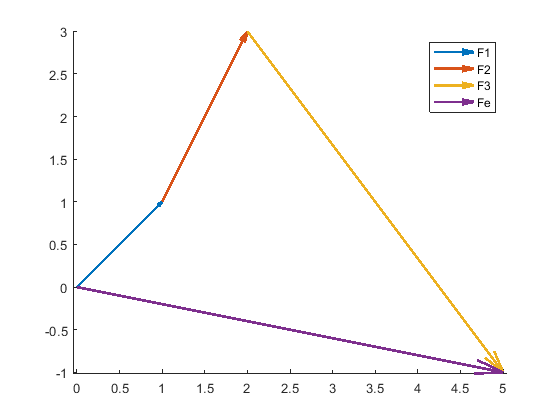

kp=[0,0];
hold on
for i=1:sizexy(1)
    vp=kp+F(i,:);
    nev="F"+i;
    quiver (kp(1),kp(2),F(i,1),F(i,2),0,'LineWidth',2,'DisplayName',nev)
    kp=vp;
end
quiver (0,0,Fe(1),Fe(2),0,'LineWidth',2,'DisplayName','Fe')
axis equal
legend